## 1. feladat

### 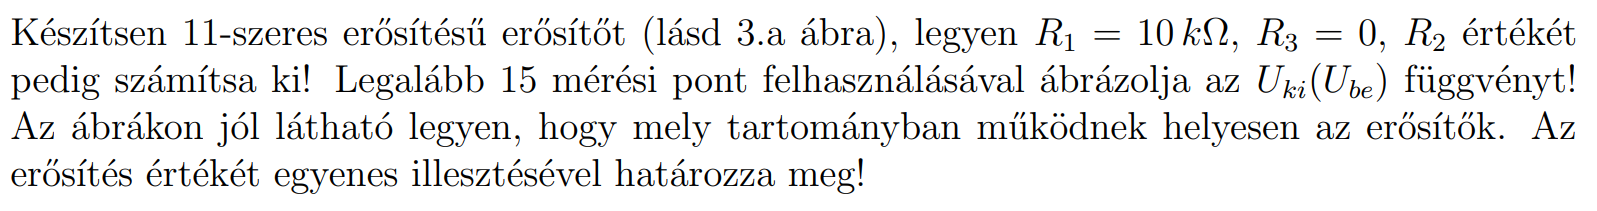

### áramkör

[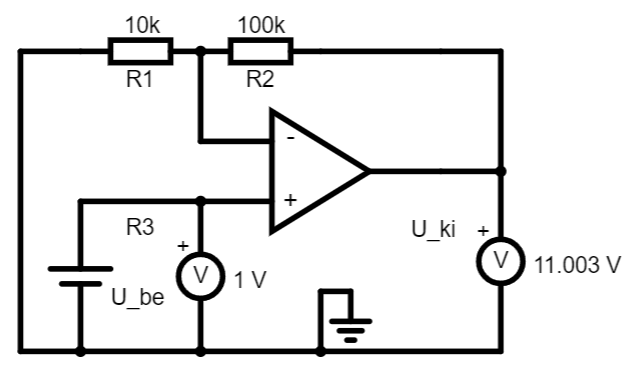](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvVDRZJx8GslhxcyMKWIJcagqxQoZkNgHNuBXmmNHe+CDT0B3FMjQhcGFGAEu9AN1fvZb7mDWUOCywdbQCGwAHijENGikUmYJvBAOIACqAPoARgxsdoLCaPxOxCaltmUVAuWx1tFOLmgIpE7+JI5pjtkA1gCWBdxYjs40QhYebAAO1SJzY05hQ0X1w47IcVBsAE7razxrsrpDh5vxhNyXentnW0ppW8fwQ6yjLm9Hr+nnPl8xmxMCDEBHoJGQ4BQjgASrhGoCUFg2shQSgiJD0tD2DE0M5EW1+JQUV0oSBoWhXh1AlcTNSqqtfhMvrNDvwLpNxss7IdFg8mg1uclkiNzNtuSLTCYRYsqjzmtKpkA)

### R_2 számítás

Visszacsatolási tényező: $\beta =\frac{R_1 }{R_1 +R_2 }$


$$V_{\textrm{in}} =V_{\textrm{out}} \cdot \;\beta =V_{\textrm{out}} \cdot \frac{R_1 }{\;R_1 +R_2 }=V_{\textrm{out}} \cdot \frac{10\ldotp 000\Omega \;}{10\ldotp 000\Omega +R_2 \;}$$



$$V_{\textrm{out}} =V_{\textrm{in}} \cdot \beta \;=\frac{V_{\textrm{in}} }{11}$$



$$\begin{array}{l}
\frac{1}{11}=\frac{10\ldotp 000\Omega \;}{10\ldotp 000\Omega +R_2 \;}\\
\frac{\left(10\ldotp 000\Omega +R_2 \right)}{11}=10\ldotp 000\Omega \;\\
10\ldotp 000\Omega +R_2 =110\ldotp 000\Omega \\
R_2 =100\ldotp 000\Omega 
\end{array}$$


### Karakterisztika mérés

V_in = [ ...
    1.317 1.031 0.904 0.82 0.666  ...
    0.527 0.412  0.353 -0.054 -0.194 ...
    -0.5 -0.707 -0.804 -1.098 -1.327 ...
];

V_out = [ ...
    10.89 10.88 10.05 8.84 7.14  ...
    5.71 4.45 3.85 -0.525 -2.07 ...
    -5.5 -7.63 -8.69 -9.35 -9.35 ...
];

measurements = table(V_in', V_out', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");2

Mért értékek


ans = 2

display(measurements);

measurements = 15×2 table
    Bemeneti feszültség (V)    Erősítő feszültsége (V)
    _______________________    _______________________

             1.317                      10.89         
             1.031                      10.88         
             0.904                      10.05         
              0.82                       8.84         
             0.666                       7.14         
             0.527                       5.71         
             0.412                       4.45         
             0.353                       3.85         
            -0.054                     -0.525         
            -0.194                      -2.07         
              -0.5                       -5.5         
            -0.707                      -7.63         
            -0.804                      -8.69         
            -1.098                      -9.35         
            -1.327       

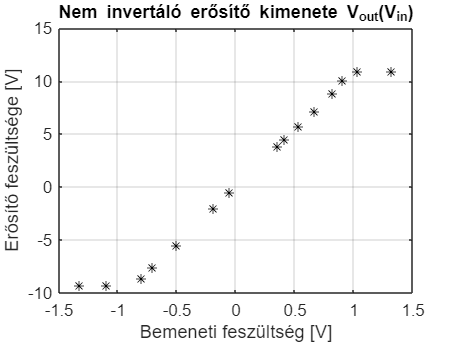



plot(V_in, V_out, "*k"); grid on;
title("Nem invertáló erősítő kimenete V_{out}(V_{in})");
xlabel("Bemeneti feszültség [V]");
ylabel("Erősítő feszültsége [V]");

## 2. feladat

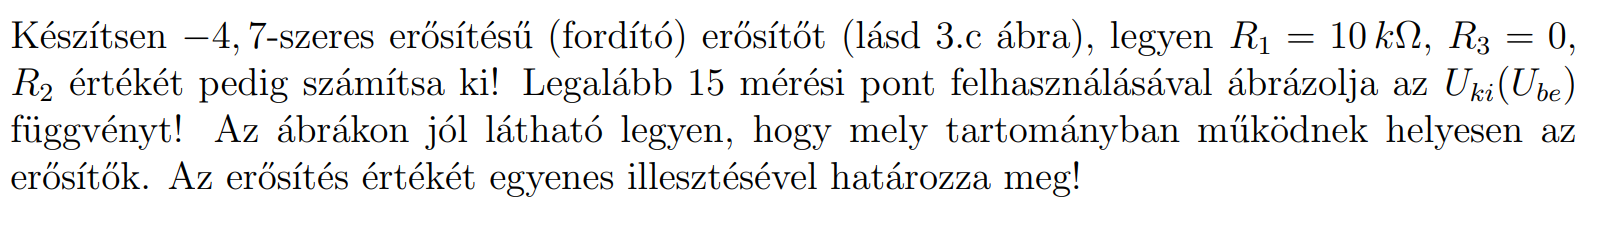

### Áramkör

[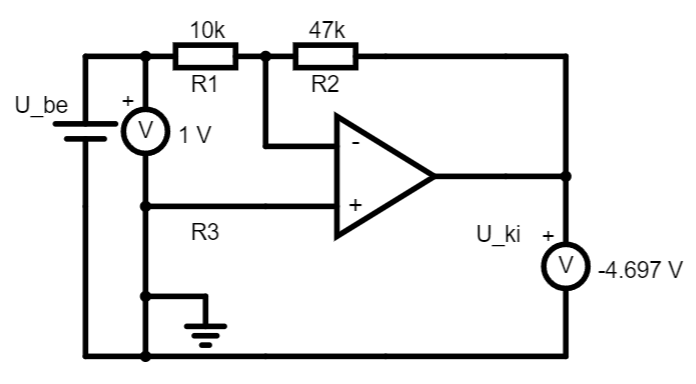](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvVDRZJx8GjHhgsyCvgoJBYMJASUa0uGwDmKLMLQExJkPgiy2AdxTI0VjCg0vbAN0fP+upyjEslDguiGy0AhsAB4gWBBKupDOSvQJzgCqAPoARgz2VkIiVsS8aPxQBUJlFdWBtrG4rmgIpFbuJM7pINkA1gCWBdjOTTR1o5UADiU1AqUeVuFVRchB3Fgpa5BsAE7rmzQ89SEK8EOEx0dH23tHq7ru9yF6Bawjrm-cmpUOn0-Ijy2MUCZQQYgI9BIyHAKGcACVcMDVhY2sgISgiDCAnD2LE0E1jG1+JQ0V1YSA4WhXh1vldvtsHIJhE86k9ttMAQk1pyvmMlg4jhMeRMGcZTOY3BAzLxRTzpZKFqLBc0NorqVLvnKJdsgA)

### R_2 számítás

Invertáló erősítő képlete: $\beta =-\frac{R_2 }{R_1 }$


$$V_{\textrm{in}} =V_{\textrm{out}} \cdot \beta \;=-V_{\textrm{out}} \cdot \frac{R_2 }{R_1 }=-V_{\textrm{out}} \cdot \frac{R_2 \;}{\;10\ldotp 000\Omega }$$



$$\begin{array}{l}
4,7=\frac{R_2 \;}{\;10\ldotp 000\Omega }\\
R_2 =47\ldotp 000\Omega \;
\end{array}$$


### Karakterisztika mérés

V_in = [ ...
    -2.826 -2.188 -1.813 -1.541 -1.02  ...
    -0.715 -0.339  -0.05 0.329 0.724 ...
    1.015 1.409 1.711 1.997 2.433 ...
];

V_out = [ ...
    10.73 10.18 8.51 7.19 4.81  ...
    3.33 1.51 0.0296 -1.11 -3.33 ...
    -4.77 -6.60 -7.94 -9.24 -9.34 ...
];

measurements = table(V_in', V_out', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 15×2 table
    Bemeneti feszültség (V)    Erősítő feszültsége (V)
    _______________________    _______________________

            -2.826                      10.73         
            -2.188                      10.18         
            -1.813                       8.51         
            -1.541                       7.19         
             -1.02                       4.81         
            -0.715                       3.33         
            -0.339                       1.51         
             -0.05                     0.0296         
             0.329                      -1.11         
             0.724                      -3.33         
             1.015                      -4.77         
             1.409                       -6.6         
             1.711                      -7.94         
             1.997                      -9.24         
             2.433       

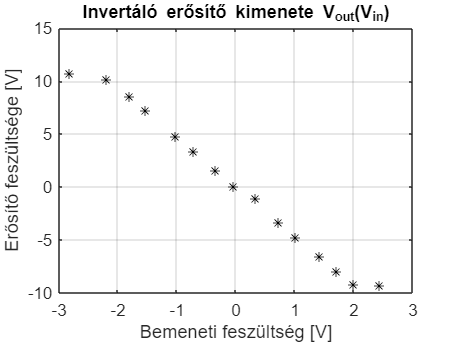



plot(V_in, V_out, "*k"); grid on;
title("Invertáló erősítő kimenete V_{out}(V_{in})");
xlabel("Bemeneti feszültség [V]");
ylabel("Erősítő feszültsége [V]");

## 3. feladat

### 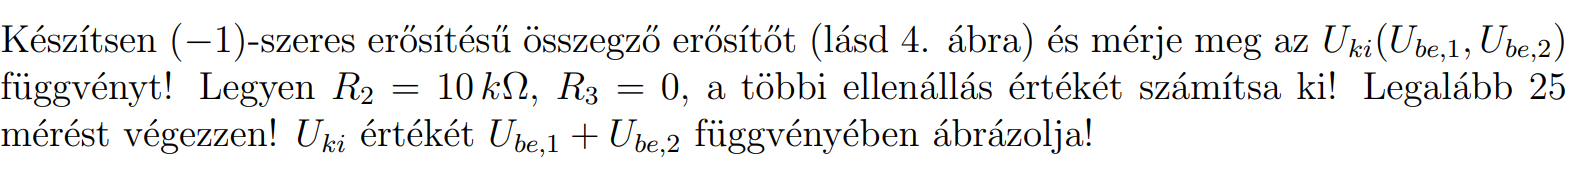

### Áramkör

[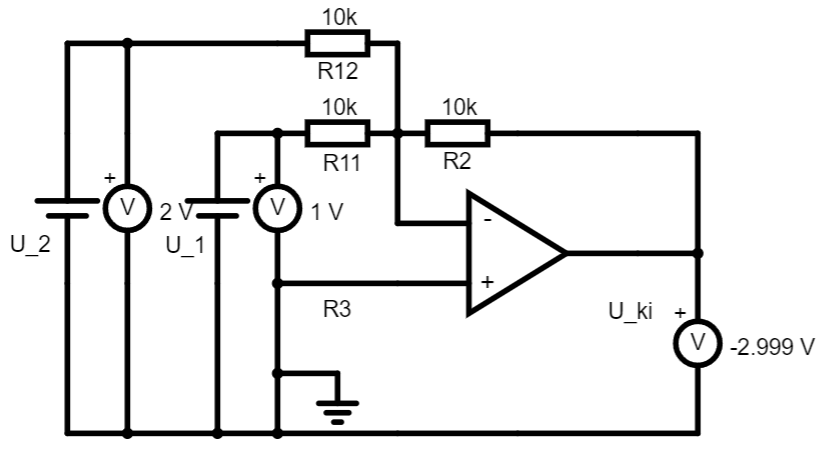](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvVDRZJx8GjHhgEYUgWK5qYSKTAEcUFDMhsA5iizC0BMWZD4IstgHcUyNDYwowA94YBuz1-w0rK7IxLJ6Gih6stAIbAAeIAQQaPz65tjgKK4AqgD67E6CGQLEvKl2jjZlItViYVAJbjRoCKQ2ntzErhAuIPkA1gCWVdiuuO5CvBP2AA51tVPNNtFVxSgNYxv2AE7cWCGbhNt60oZOPCeXl4Z7l6FBnQ+nMlXBy++BjU7vz8hPDUMiVC5QQYgI9BIyCyfQASrgmiCUAQggR2sgITDXLDWE00BNTO1+JQMT1siBYWg3p0vtdIucbEITktnoZ5v9eg0OdxIvR7BdjjMPF5+aZzJZhdwJQzuRYxJ0hQzLkKtorqSlIrLpWtxpMAvS2H4CV8CayIi1olBYoi+JDISQsf08lT5sROTQ3TyaHzvm5-CBPe8GZ6vp61U4w+53uGAyK-THA31uUGdf7TYCqoGGonXLduMdfk8+kFXgKxH17hngcQpLhoRiSbgIL1sS42EA)

### R_11 és R_12 számítás

Invertáló erősítő képlete: $\beta_x =-\frac{R_2 }{R_{1x} }$


$$V_{\textrm{out}} =\left(-V_1 \beta_1 \;-V_2 \beta {\;}_2 \right)=-V_1 \cdot \frac{10\ldotp 000\Omega \;}{R_{11} }-V_2 \cdot \frac{10\ldotp 000\Omega \;}{R_{12} }$$



$$\begin{array}{l}
-1=-\frac{10\ldotp 000\Omega \;}{R_{11} }=-\frac{10\ldotp 000\Omega \;}{R_{12} }\\
R_{11} =10\ldotp 000\Omega \\
R_{12} =10\ldotp 000\Omega 
\end{array}$$


### Karakterisztika mérés

V_in_1 = [ ...
    -5.58 -5.08 -4.06 -3.04 -2.041  ...
    -0.96 -0.0013 1 2.075 3.085 ...
    4.07 5.09 5.11 7.05 -5.14 ...
    -3.06 -1.006 5.15 5.15 -6.06 ...
    3.56 8.42 8.42 -4.92 7.08 ...
];

V_in_2 = [ ...
    -5.29 -5.07 -4.01 -3.02 -2.089  ...
    -0.97 0.001 1.071 2.117 3.112 ...
    4.02 5.01 -5.06 -7.07 5.07...
    3.03 -3.04 -3.04 2.08 2.08 ...
    -2.3 1.83 -3.39 -3.39 -2.99 ...
];

V_out = [ ...
    10.79 10.22 8.14 6.11 4.15 ...
    1.952 0.002 -2.079 -4.19 -6.23 ...
    -8.15 -9.27 -0.007 0.086 0.028 ...
    0.001 4.09 -2.07 -7.26 3.97 ...
    -1.2 -9.27 -5 8.37 -4.08...
];

measurements = table(V_in_1', V_in_2', V_out', ...
    'VariableNames', ["Bemeneti feszültség 1 (V)", "Bemeneti feszültség 2 (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 25×3 table
    Bemeneti feszültség 1 (V)    Bemeneti feszültség 2 (V)    Erősítő feszültsége (V)
    _________________________    _________________________    _______________________

               -5.58                       -5.29                       10.79         
               -5.08                       -5.07                       10.22         
               -4.06                       -4.01                        8.14         
               -3.04                       -3.02                        6.11         
              -2.041                      -2.089                        4.15         
               -0.96                       -0.97                       1.952         
             -0.0013                       0.001                       0.002         
                   1                       1.071                      -2.079         
           

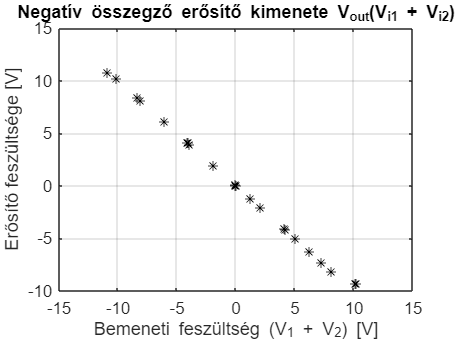



plot(V_in_1 + V_in_2, V_out, "*k"); grid on;
title("Negatív összegző erősítő kimenete V_{out}(V_{i1} + V_{i2})");
xlabel("Bemeneti feszültség (V_i_1 + V_i_2) [V]");
ylabel("Erősítő feszültsége [V]");

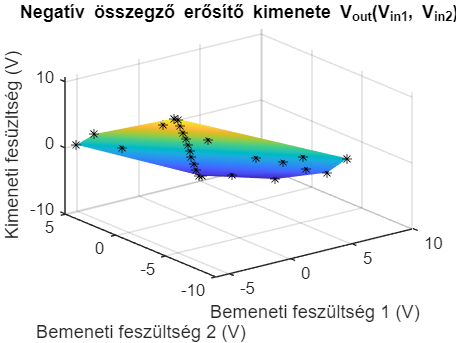


plot3(V_in_1, V_in_2, V_out, '*k'); grid on;
title("Negatív összegző erősítő kimenete V_{out}(V_{in1}, V_{in2})");
xlabel("Bemeneti feszültség 1 (V)");
ylabel("Bemeneti feszültség 2 (V)");
zlabel("Kimeneti fesüzltség (V)");

hold on;
dt = delaunayTriangulation(V_in_1', V_in_2');
tri = dt.ConnectivityList ;
xi = dt.Points(:,1) ; 
yi = dt.Points(:,2) ; 
F = scatteredInterpolant(V_in_1', V_in_2', V_out');
zi = F(xi,yi) ;

trisurf(tri,xi,yi,zi);
shading interp
hold off;

## 4. feladat

### 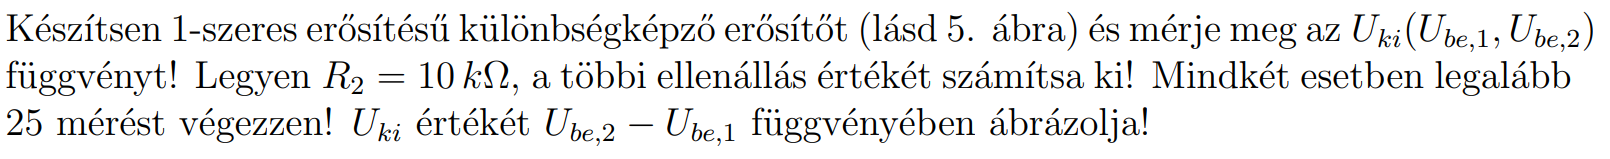

### Áramkör

[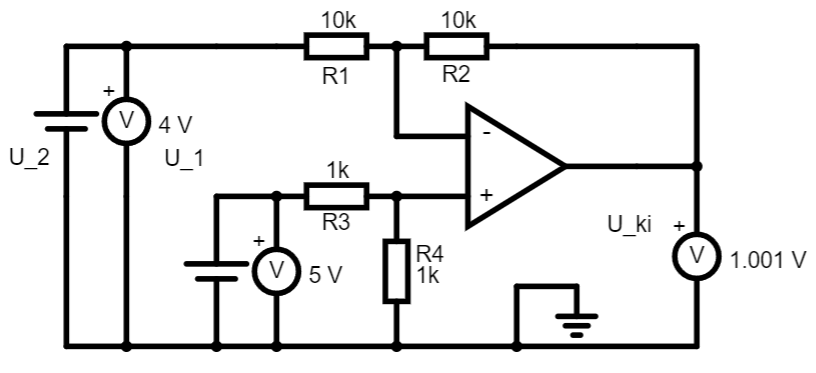](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvVDRZJx8GmmjVIYZGHLIscZMWFypMyGwDmIfBDQFeJ44qhQ2AdxTI0xjCjADX+gG6PnuV6zO-DQh4DRIoTAIbAAeIASm-CiQ2tjgKM4AqgD67A6CqQLEvGhJ+vnFIsaVmiGxLrIIpMbu3MTOEE4gOQDWAJb23Fh+rkIWnmwADtUlSWMNxjblxkIoxLLDa3UATkPOtdyEWzbSyzzH5+f6u+cHyp3rJzKDgcf3x-pxmiUIYgT0JGQ6S6ACVcPVvigCDRkP8ofROs4Qew4mh-CgsM1+JRYR0MiAQWhBgVjvMDvppu9gm4PDR6HUHOd-DDWszbPlrGYSpsuezDuMNiMGS4Fujqd4RdT0eSbGAaBBIvIIXwAQCSMCstkidNiA8aLruHLFsKDdSDWzluaAl0LYMrXShXzsEFzHsFstXtSqUbltLHgbyXa9b4PmwbkdqUzPMk4GGaYbZBGfTHPtxYUMkGiAVheIiCWA2EA)

### R_1, R_3 és R_4 számítás

Inveráló erősítő képlete: $\beta \;=-\frac{R_2 }{R_1 }$


$$\begin{array}{l}
\beta =1\Rightarrow R_2 =R_1 =10k\Omega \;\\
\beta =1\Rightarrow R_3 =R_4 =\textrm{tetszőleges}\;\left(1k\Omega \;\right)
\end{array}$$


### Karakterisztika mérés

V_in_1 = [ ...
    10.23 4.98 0.0014 -4.96 -10.27 ...
    0.0015 0.0015 0.0015 0.0015 0.0015 ...
    -10.27 -5.19 0.008 4.96 10.22 ...
    2.53 2.53 4 4 -7.67...
    -7.67 -2.47 -2.47 3.59 3.59...
];

V_in_2 = [ ...
     -0.003 -0.003 -0.003 -0.003 -0.003 ...
     10 5.05 -0.014 -5.05 -10.14 ...
     -10.13 -5.18 0.0015 4.98 10.09 ...
     6.95 -5.67 -5.67 1.58 1.58 ...
     -10.13 -10.13 4.07 4.07 -6.01 ...
];

V_out = [ ...
    10.3 5.02 0.005 -5 -9.32 ...
    -9.27 -5.1 0.018 5.12 10.26 ...
    -0.089 0.013 0.007 -0.045 0.088 ...
     -4.48 8.28 9.79 2.45 -9.27 ...
     2.53 7.77 -6.6 -0.499 9.69 ...
];

measurements = table(V_in_1', V_in_2', V_out', ...
    'VariableNames', ["Bemeneti feszültség 1 (V)", "Bemeneti feszültség 2 (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 25×3 table
    Bemeneti feszültség 1 (V)    Bemeneti feszültség 2 (V)    Erősítő feszültsége (V)
    _________________________    _________________________    _______________________

              10.23                       -0.003                        10.3         
               4.98                       -0.003                        5.02         
             0.0014                       -0.003                       0.005         
              -4.96                       -0.003                          -5         
             -10.27                       -0.003                       -9.32         
             0.0015                           10                       -9.27         
             0.0015                         5.05                        -5.1         
             0.0015                       -0.014                       0.018         
           

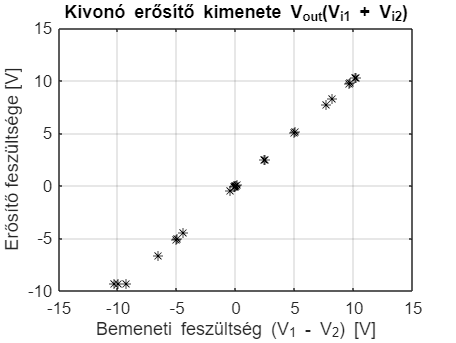



plot(V_in_1 - V_in_2, V_out, "*k"); grid on;
title("Kivonó erősítő kimenete V_{out}(V_{i1} + V_{i2})");
xlabel("Bemeneti feszültség (V_i_1 - V_i_2) [V]");
ylabel("Erősítő feszültsége [V]");

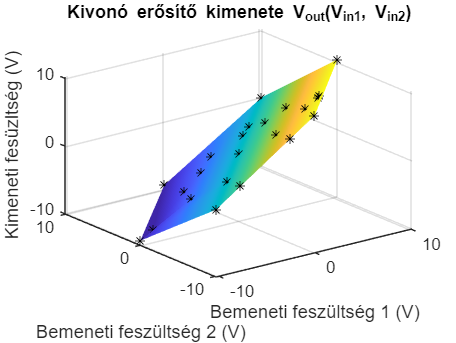


plot3(V_in_1, V_in_2, V_out, '*k'); grid on;
title("Kivonó erősítő kimenete V_{out}(V_{in1}, V_{in2})");
xlabel("Bemeneti feszültség 1 (V)");
ylabel("Bemeneti feszültség 2 (V)");
zlabel("Kimeneti fesüzltség (V)");

hold on;
dt = delaunayTriangulation(V_in_1', V_in_2');
tri = dt.ConnectivityList ;
xi = dt.Points(:,1) ; 
yi = dt.Points(:,2) ; 
F = scatteredInterpolant(V_in_1', V_in_2', V_out');
zi = F(xi,yi) ;

trisurf(tri,xi,yi,zi);
shading interp
hold off;

## 5. feladat

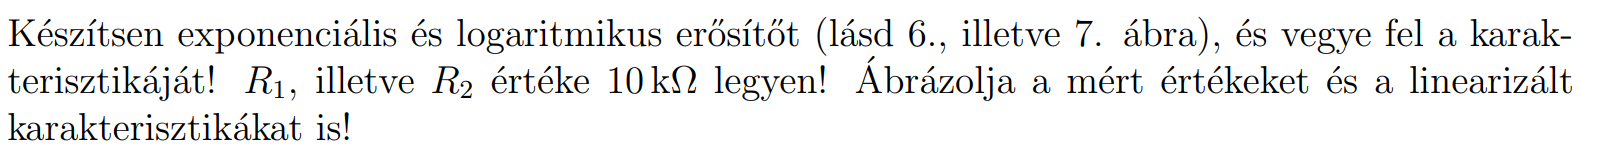

### áramkör

Exponenciális áramkör

[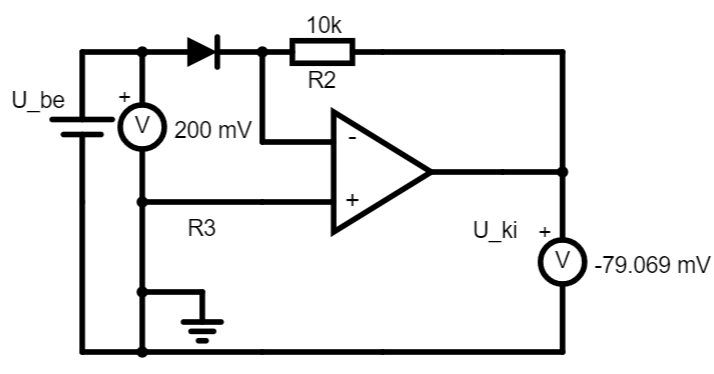](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvVDRZJx8GjHhg0CLKUhkFBZMQIQa0uGwDmKLMLQExJkPh1Q2AdxTI0VjCjADXkNgDdHz-rpOKMSyUOCy0Bgy0TLIvKEwCGwAHiBYEMgqKJDOmfQZzgCqAPoARgz2VkIiVlo1Xg5CvGj8tWIhtqm4roqkVu7cxM4FICUA1gCWldjO3TRNLrJsAA5tNQtzVmENVcKaNDPBSwBO3Fi5HTxHYXrThNdXVzuss64v3GBLDu-7bhkdXlSmmaCDEBHoJGQ4BQzgASrgUtxusY+vxKHFhjCQLC0JVkAMAtx7oSdoI9h0Fr8vKt8f9dATPlsvkTeJtaYtbN9LGYxATzJy-tx+ezNjsrptDqK8Qz6RAebYACaC35XFUgBUMABmHAArgAbAAubFwrJAADEoRJ-CAWCAAGoAe0NHAMFSAA) 

Logaritmikus áramkör

[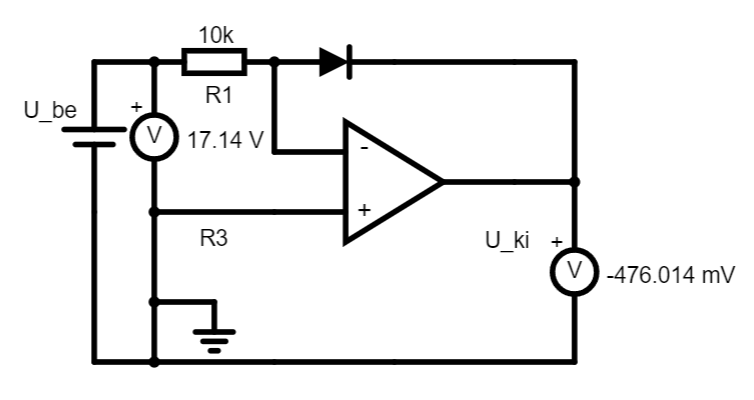](https://falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgBDEDA7tCXLmJ8IvVDRZJx8GjHhg0FYpGRhcWYgSwrhNaXDYBzFBu4Exp-BFlsA7imRoQuDCjADXkNgDcHT-nqOKMpQoWB6WNCqobLQCGwAHiBYEMikepBOafSpTgCqAPoARgx2zkIizpqVXvZCvGj8VWIhXkkuNGgIpM7u3MROuSCFANYAlmXYTh3Nzp5sAA6zjQLVM-Q2dRXIIVPBNgBO3IT7bqmtKDKTJzudJzxQZazTrs-c4Y-2b7dnp23BDQQYgI9BIyHAKCcACVcIkTODkEQUARhIikEMoewvn0AscGh9auVUSF6n9Fr8fqoILiNp88XM9H0ZoTkKY0OZfuzeCycRyqQy6Q8ZntmU8cR9+VzHgATek-PbykDShgAMw4AFcADYAFzYuF49AAYuCJP4JOCAGoAex1HEMpSAA)

### Segéd függvény

loglin = @(totalCount, f_floor, f_ceiling) ...
    f_floor .* (f_ceiling/f_floor) .^ ((0:(totalCount -1)) / (totalCount - 1));


### Exponenciális áramkör mérések

V_in = [ ...
    0.421 0.457 0.475 ...
     0.509 0.533 0.551 0.56 0.6 0.7 ...
];

V_out = [ ...
    -0.392 -1.017 -1.565...
    -3.32 -5.58 -8.01 -9.18 -9.27 -9.27 ...
];

measurements = table(V_in', V_out', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 9×2 table
    Bemeneti feszültség (V)    Erősítő feszültsége (V)
    _______________________    _______________________

             0.421                     -0.392         
             0.457                     -1.017         
             0.475                     -1.565         
             0.509                      -3.32         
             0.533                      -5.58         
             0.551                      -8.01         
              0.56                      -9.18         
               0.6                      -9.27         
               0.7                      -9.27         


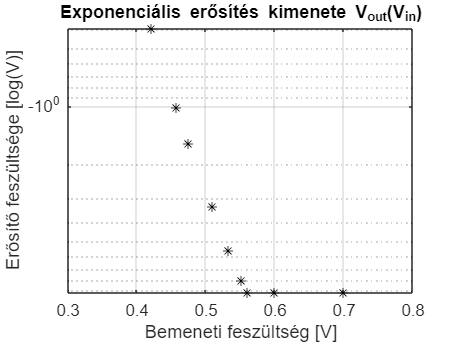



semilogy(V_in, V_out, "*k"); grid on;
title("Exponenciális erősítés kimenete V_{out}(V_{in})");
xlim([0.3 0.8])
xlabel("Bemeneti feszültség [V]");
ylabel("Erősítő feszültsége [log(V)]");

### Logaritmikus áramkör mérések

V_in = [ ...
    0.016 0.0318 0.045 0.051 0.0808...
    0.101 0.197 0.293 0.396 0.602 ...
    0.79 1.006 2.066 4.05 7.04  ...
    10.23
];

V_out = [ ...
    -0.314 -0.334 -0.348 -0.351 -0.366 ...
    -0.373 -0.395 -0.409 -0.420 -0.436 ...
    -0.446 -0.456 -0.487 -0.518 -0.544 ...
    -0.562
];

measurements = table(V_in', V_out', ...
    'VariableNames', ["Bemeneti feszültség (V)", "Erősítő feszültsége (V)"]);
disp("Mért értékek");

Mért értékek


display(measurements);

measurements = 16×2 table
    Bemeneti feszültség (V)    Erősítő feszültsége (V)
    _______________________    _______________________

             0.016                     -0.314         
            0.0318                     -0.334         
             0.045                     -0.348         
             0.051                     -0.351         
            0.0808                     -0.366         
             0.101                     -0.373         
             0.197                     -0.395         
             0.293                     -0.409         
             0.396                      -0.42         
             0.602                     -0.436         
              0.79                     -0.446         
             1.006                     -0.456         
             2.066                     -0.487         
              4.05                     -0.518         
              7.04       

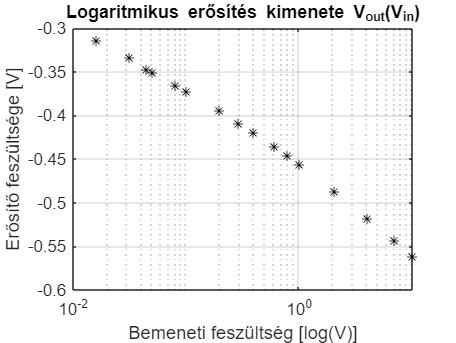



semilogx(V_in, V_out, "*k"); grid on;
title("Logaritmikus erősítés kimenete V_{out}(V_{in})");
xlabel("Bemeneti feszültség [log(V)]");
ylabel("Erősítő feszültsége [V]");

## 6. feladat

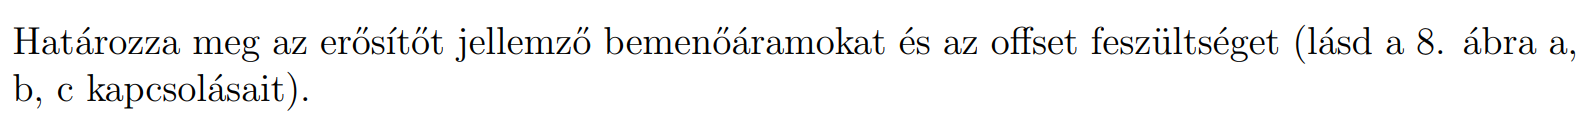

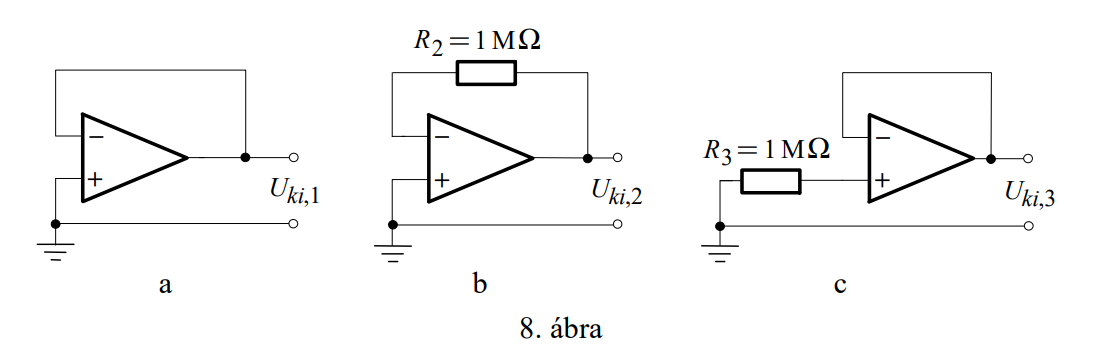

MÉRÉS!!!

### a ábra

Bemenet földelve van, így virtális földet hoz létre az erősítő eltolva a $V_{\textrm{offset}} -\textrm{el}$


$$\begin{array}{l}
V_{\mathrm{egyenes}} =0V\;\left(\mathrm{föld}\right)\\
V_{\mathrm{fordított}} =V_{\mathrm{kimenet}} =0V\;\left(\mathrm{virtuális}\;\mathrm{föld}\right)+V_{\mathrm{offset}} 
\end{array}$$



$$V_{\mathrm{offset}} =V_{\mathrm{kimenet}} =-0\ldotp 01\mathrm{mV}$$


### b ábra


$$\begin{array}{l}
V_{\mathrm{egyenes}} =0V\;\left(\mathrm{föld}\right)\\
V_{\mathrm{fordított}} =0V\;\left(\mathrm{virtuális}\;\mathrm{föld}\right)+V_{\mathrm{offset}} +I_{\mathrm{offset}} \cdot R_2 
\end{array}$$



$$\begin{array}{l}
V_{\mathrm{kimenet}} =33\mathrm{mV}\\
V_{R_2 } =32\ldotp 7\mathrm{mV}\\
V_{\mathrm{offset}} =V_{\mathrm{kimenet}} -V_{R_2 } =0,3\mathrm{mV}
\end{array}$$


### c ábra


$$\begin{array}{l}
V_{\mathrm{egyenes}} =0V\;\left(\mathrm{föld}\right)\\
V_{\mathrm{fordított}} =0V\;\left(\mathrm{virtuális}\;\mathrm{föld}\right)+V_{\mathrm{offset}} -I_{\mathrm{offset}} \cdot R_2 
\end{array}$$



$$\begin{array}{l}
V_{\mathrm{kimenet}} =29\mathrm{mV}\\
V_{R_2 } =28\ldotp 7V\\
V_{\mathrm{offset}} =V_{\mathrm{kimenet}} -V_{R_2 } =0,3\mathrm{mV}
\end{array}$$
